---

title: "PEP_wp4_beh"

output: html_document

date: "2023-12-15"

--- house keeping ---

% clear workspace
clear;
clc;

% set working directory
wd = 'C:/Users/JLU-SU/OneDrive - Justus-Liebig-Universität Gießen/Dokumente/GitHub/pep_wp4_analysis';
cd(wd);

function_folder = fullfile(pwd, 'functions')

function_folder = 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_analysis\functions'

addpath(function_folder)

--- loading files ---

% details of subjects
d.subNums = [101, 102, 103, 104];
d.n = length(d.subNums);

% load files using costum function
d = load_files(d);

    "1210"    "C:\Users\JLU-SU\OneDrive - Justus-Lie…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Lie…"

    "1220"    "C:\Users\JLU-SU\OneDrive - Justus-Lie…"

    "1230"    "C:\Users\JLU-SU\OneDrive - Justus-Lie…"



--- simulate additional subjects ---

% based on each subject, how many additional subjects should be simulated
sim_para.sim_subs = 10;

% Set parameters
sim_para.RT_sd = 0.5;
sim_para.acc_sd = 0.8;
sim_para.rating_sd = 0.8;
sim_para.baseline_sd = 0.2;

% use costum function to simulate data 
d = sim_new_subs(d, sim_para);

--- transfrom data ---

% transform data using costum function (adds a couple new subtables)
d = transform_data(d);

%% CHECK If RATING ARE CORRECT

--- performance --- 

% call costum function to calculate performance
perf = make_perf(d);


--- HISTOGRAMS ---

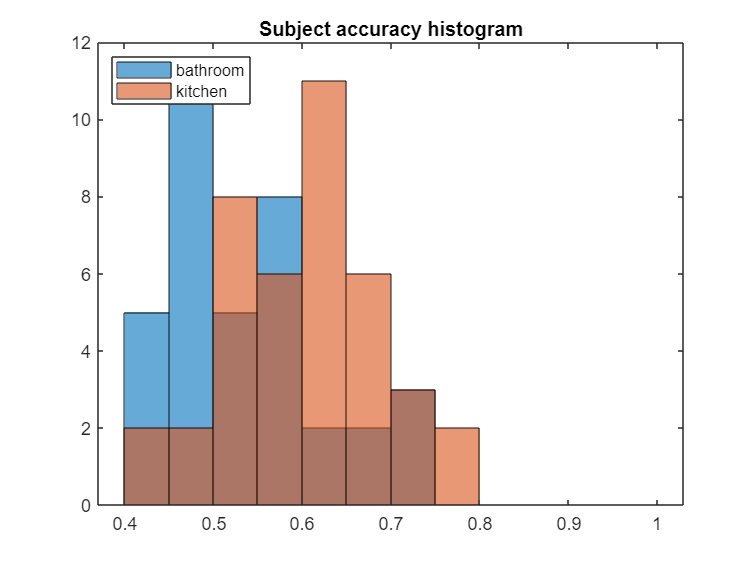

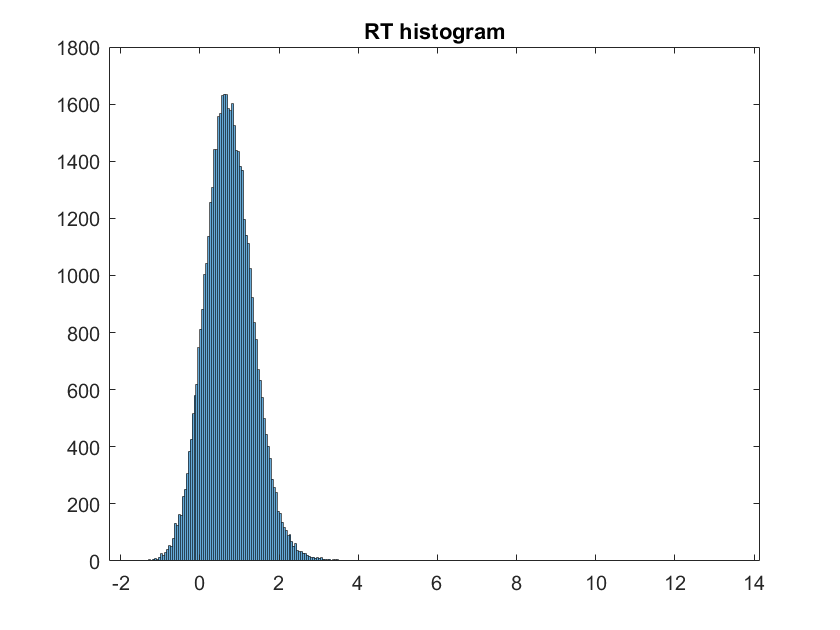

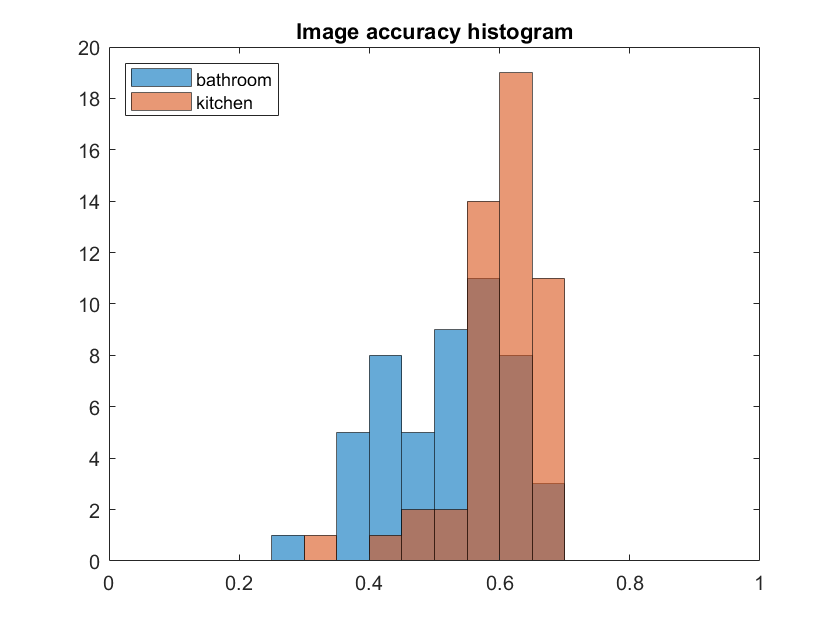

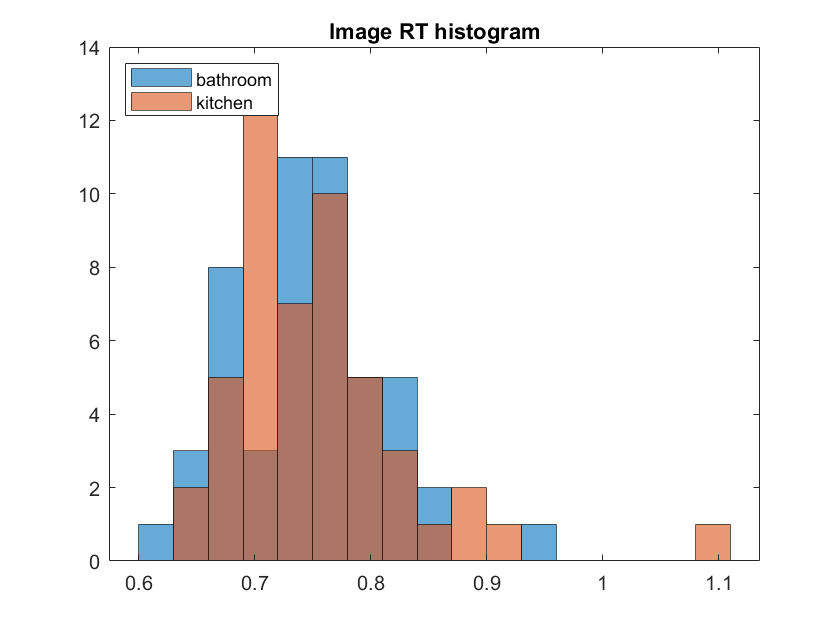

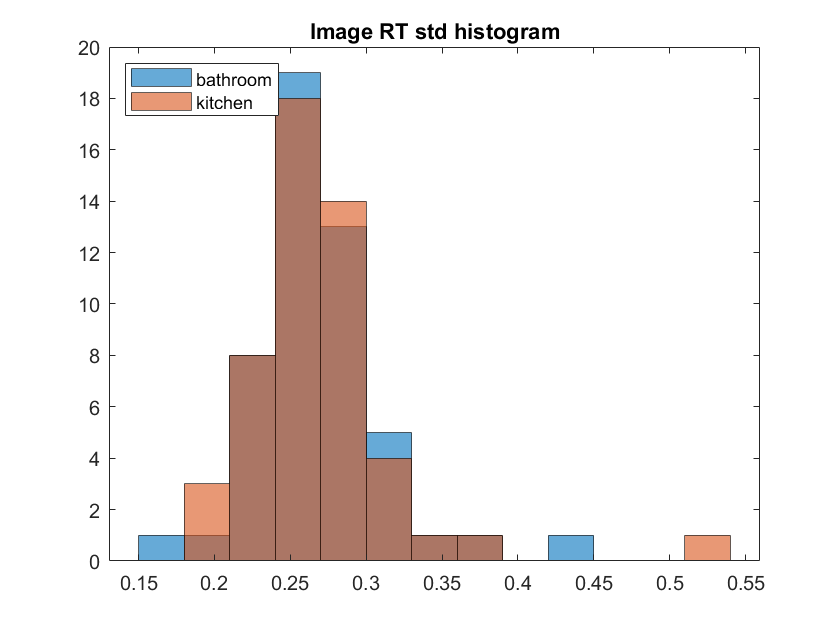

hist_plots = struct with fields:
    hist_sub_acc: [1×1 Histogram]
         hist_RT: [1×1 Histogram]
        hist_acc: [1×1 Histogram]
     hist_img_RT: [1×1 Histogram]
     hist_RT_std: [1×1 Histogram]


% call costum function to plot histograms
hist_plots = hist_plots(d)

--- timing ----

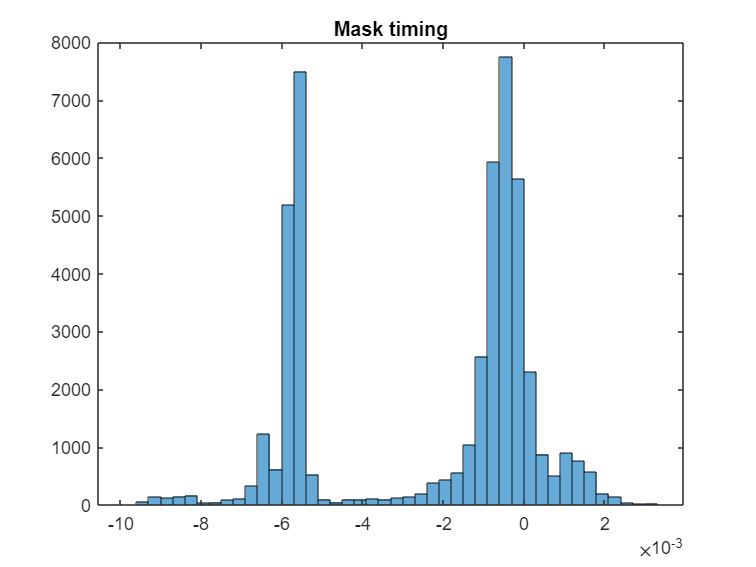

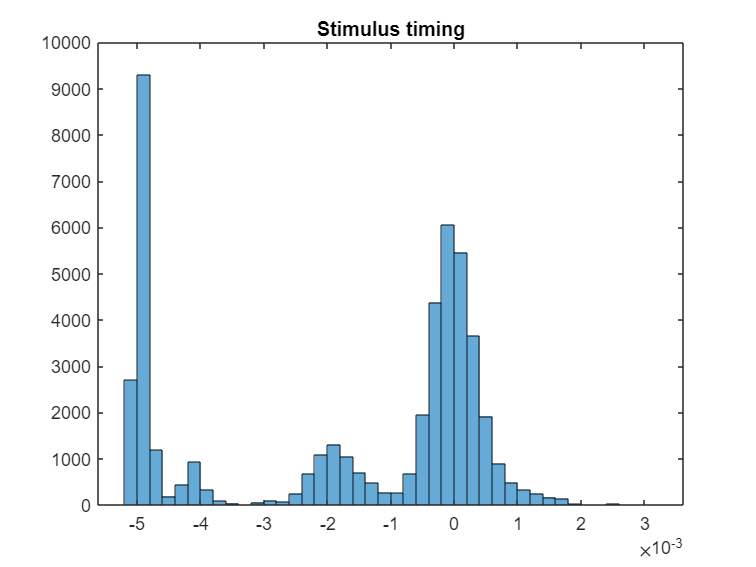

% call costum function to calculate and plot the timing
timing = calculate_timing(d);

--- rating correlation ---

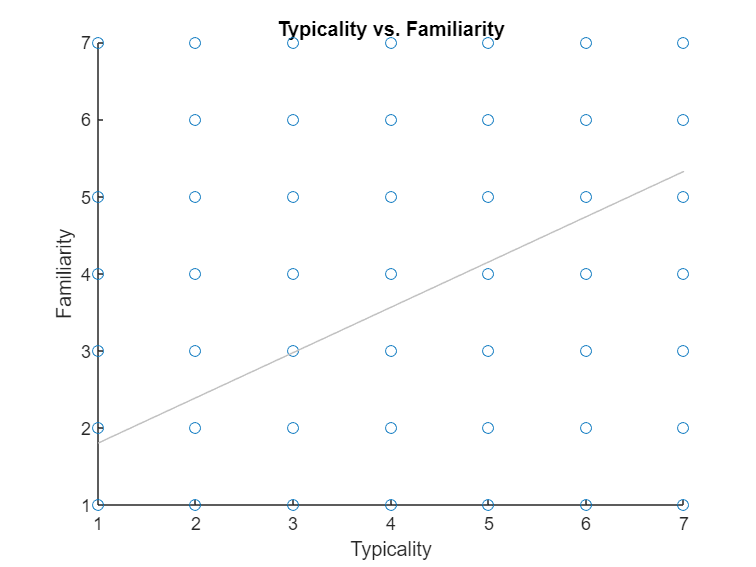

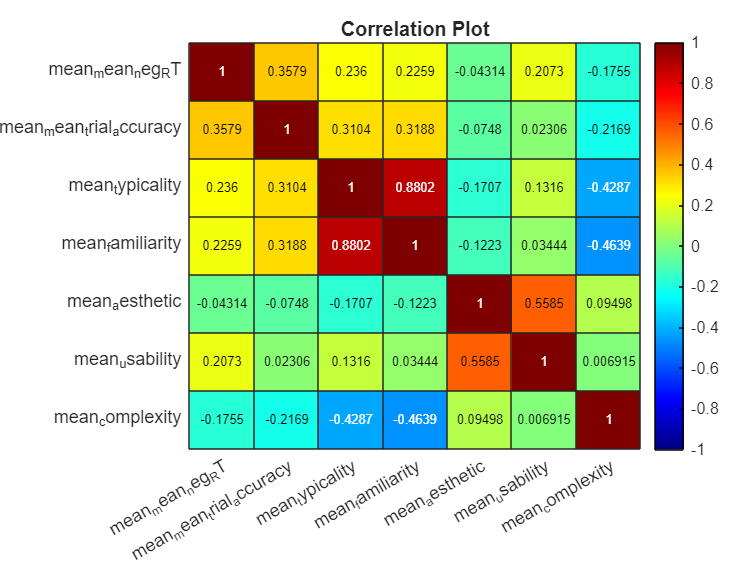

rating_rating_cor_plots = struct with fields:
    cor_plots: [1×1 struct]


% call costum function to calculate and plot the correlations of rating on
% population level
rating_rating_cor_plots = plot_rating_cor(d)

--- intersubject correaltions ---

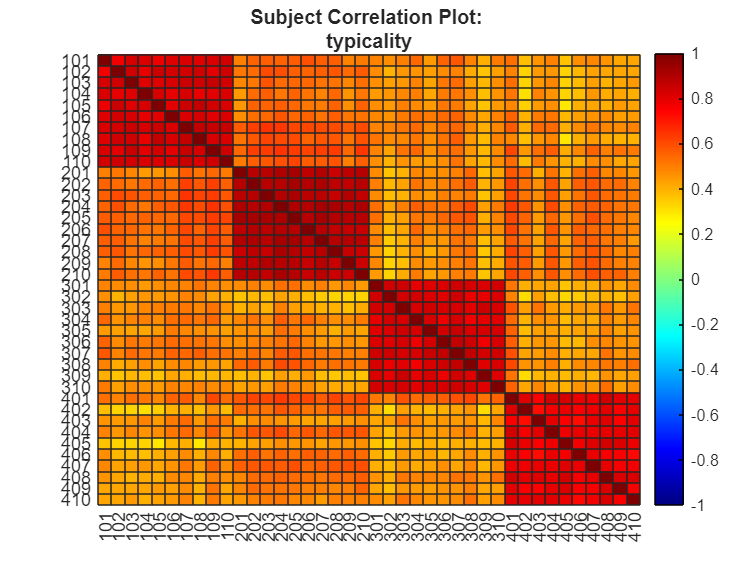

Arrays have incompatible sizes for this operation.

Error in intersub_cor (line 49)
if tril(d.ratingRDM(1).RDM) == d.ratingVEC(count).vec

Related documentation

% call costum function to calculate and plot the correlations of rating between subjects
cor_plots = intersub_cor(d);